# **Preprocess Measured Data from Pump**

**Create Datastore**

A collection of measurement data from pumps has been saved to .CSV files.  To process them more efficiently, we will set up a datastore.  The datastore allows us to process data stored in files with arbitrary names in multiple folders, even if individual files would be too large to completely load into memory.

datastore_dir = fileparts(which('sm_pump_triplex_DOEdata_process.mlx'));
ds = datastore([datastore_dir filesep 'Data' filesep ...
    'PumpData*.csv']);

**Preview Datastore**

pre = preview(ds)

pre = 8×7 table
     time     iMotor      pIn        pOut      qOut     wMotor       fault   
    ______    ______    ________    ______    ______    ______    ___________

    2.3831    26.836    -0.13368    7.2172    34.625    1920.2    {'Leak P1'}
    2.3841    26.645    -0.16104    7.2196    35.271    1916.7    {'Leak P1'}
    2.3851    26.504    -0.18035    7.2286    36.426    1914.4    {'Leak P1'}
    2.3861    26.413    -0.19116    7.2418    37.907    1913.2    {'Leak P1'}
    2.3871    26.326    -0.19814    7.2531    39.108    1911.3    {'Leak P1'}
    2.3881    26.285    -0.19616    7.2647    40.285    1910.1    {'Leak P1'}
    2.3891    26.327    -0.18029    7.2795    41.722    1910.9    {'Leak P1'}
    2.3901    26.263    -0.17336    7.2773 

## **Plot All Raw Data **

This code will loop through the files in the datastore and plot the output pressure data.  There are many data traces to be plotted, and it appears the data will need to be preprocessed.

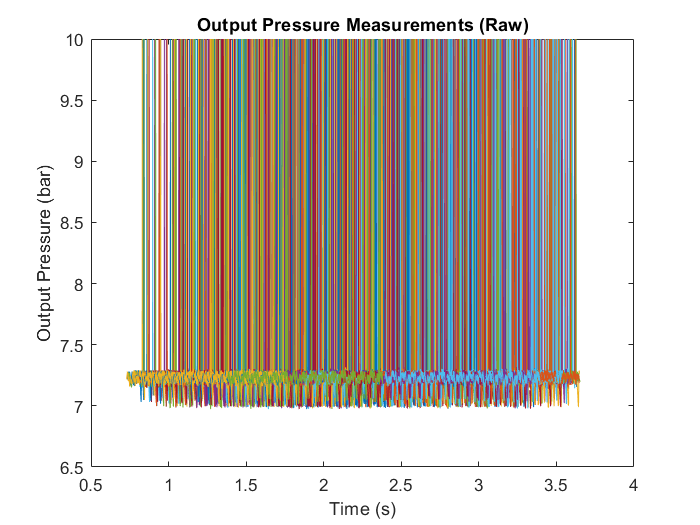

reset(ds)
figure;
while hasdata(ds)
    T=read(ds);
    plot(T.time,T.pOut);
    hold on
end
hold off
reset(ds)
xlabel('Time (s)')
ylabel('Output Pressure (bar)');
title('Output Pressure Measurements (Raw)')

## **Plot Two Traces to Check for Issues**

Looking at two traces, we can see a number of problems with the raw data

- The data has noise (spikes up to the sensor's maximum value)

- The data has gaps (points where no data was measured)

- The data is offset in time - even though the duration of the traces is the same, different measurement delays precede the traces.

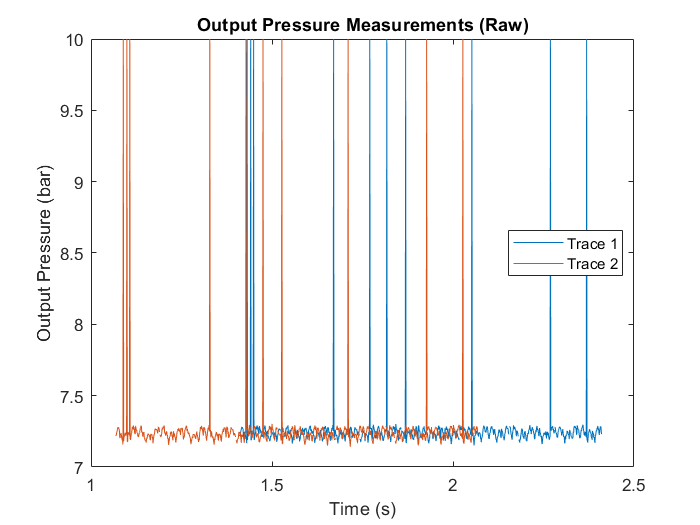

reset(ds)
figure;
T=read(ds);  
plot(T.time,T.pOut);
hold on
T=read(ds);  
plot(T.time,T.pOut);
hold off
reset(ds)
xlabel('Time (s)')
ylabel('Output Pressure (bar)');
title('Output Pressure Measurements (Raw)')
legend({'Trace 1','Trace 2'},'Location','Best')

## Preprocess Data

We will use tall tables to process the data.  Processing using tall tables enables MATLAB to collect the operations to be performed on the data and perform them in the most efficient way, minimizing the number of passes through the data.

Here are the steps for preprocessing the measurement data:

- Remove outliers (values at the limit of the sensor)

- Fill in gaps where no data was taken

This plot shows the original and processed data.

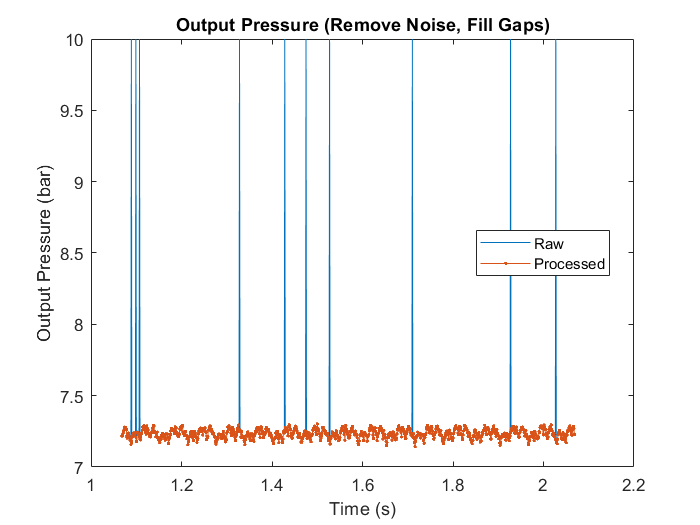

% Save original for comparison
T_orig = T;

% Replace noise and gaps with linearly interpolated data
idx_Noise = T.pOut>9;
T.pOut(idx_Noise) = NaN;
idx_Missing = isnan(T.pOut);
T.pOut = fillmissing(T.pOut,'linear');

figure;
plot(T_orig.time, T_orig.pOut)
hold on
plot(T.time, T.pOut,'-','Marker','.')
hold off
xlabel('Time (s)')
ylabel('Output Pressure (bar)');
title('Output Pressure (Remove Noise, Fill Gaps)')
legend({'Raw','Processed'},'Location','Best')

## Preprocess All Data

Now that we have tested our data processing steps on one trace, we will apply these operations on all of the collected data.  The plot below shows all of the output pressure data after processing.  It is ready for feature extraction to create training data for a classification model for a predictive maintenance algorithm.

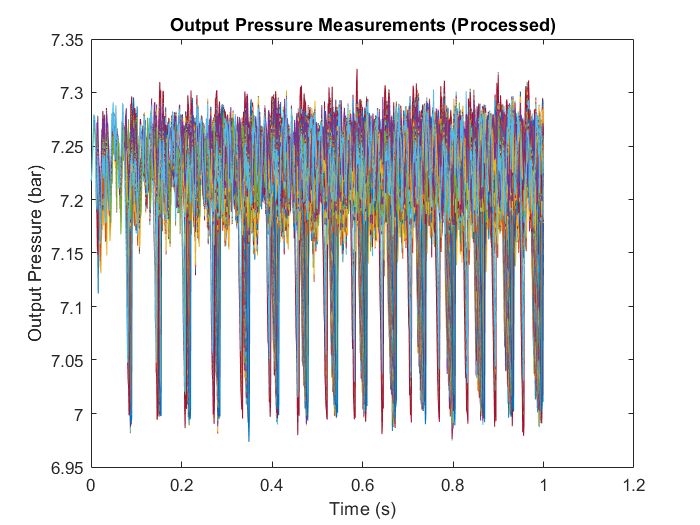

reset(ds)
figure;
while hasdata(ds)
    T=read(ds);
    idx_Noise = T.pOut>9;
    T.pOut(idx_Noise) = NaN;
    idx_Missing = isnan(T.pOut);
    T.pOut = fillmissing(T.pOut,'linear');
    T.time = T.time-T.time(1);
    plot(T.time,T.pOut);
    hold on
end
hold off
reset(ds)
xlabel('Time (s)')
ylabel('Output Pressure (bar)');
title('Output Pressure Measurements (Processed)')